# Question - 1 (PART - III)

% Clear workspace and command window
clear; clc; close all;
% For reproducibility
rng(27); 

## Load data

% Load data
raw_data = readtable("../../dataset/medical_insurance.csv");
age = table2array(raw_data(:,1));
[~, ~, sex] = unique(raw_data(:, 2));
bmi = table2array(raw_data(:,3));
children = table2array(raw_data(:,4));
[~, ~, smoker] = unique(raw_data(:, 5));
[~, ~, region] = unique(raw_data(:, 6));
charges = table2array(raw_data(:,7));

% Combine the encoded data
encoded_data = [age sex bmi children smoker region charges];
% Separate dependent and independent variables
X = encoded_data(:, 1:6);
Y = encoded_data(:, 7);

## Splitting the data

cv = cvpartition(numel(Y), 'HoldOut', 0.2); % 20% for testing
idx_train = training(cv);
idx_test = test(cv);
X_train = normalize(X(idx_train, :));
Y_train = Y(idx_train);
X_test = normalize(X(idx_test, :));
Y_test = Y(idx_test);

## Initialize variables

alpha = 0.005; % Learning rate
epochs = [450, 150, 1000]; % Epochs or Number of Iterations

## Perform Regression

[beta_hat_ols, cost_history_ols] = ordinaryLeastSquares(X_train, Y_train, alpha, epochs(1));
[beta_hat_lms, cost_history_lms] = leastMedianSquares(X_train, Y_train, alpha, epochs(2));
[beta_hat_lts, cost_history_lts] = leastTrimmedSquares(X_train, Y_train, alpha, epochs(3));

## Display best parameters

% Model parameter names
parameters = {'intercept', 'beta1', 'beta2', 'beta3', 'beta4', 'beta5', 'beta6'};
methods = {'OLS', 'LMS', 'LTS'};
TP = table(beta_hat_ols, beta_hat_lms, beta_hat_lts, 'VariableNames', methods);
TPD = table(parameters', TP, 'VariableNames', {'Parameters', 'Optimum'});
disp(TPD);

    Parameters                Optimum           
                     OLS        LMS        LTS  
    ___________    _____________________________

    'intercept'      11905      10354     4676.8
    'beta1'         3195.8       2756     2265.1
    'beta2'         185.05     273.62    -297.75
    'beta3'         1817.7     1620.4     52.252
    'beta4'         663.02     598.23     998.51
    'beta5'         8549.9     7415.1    -2385.2
    'beta6'        -394.55    -307.36    -216.83



## Model Testing

**Ordinary Least Squares**

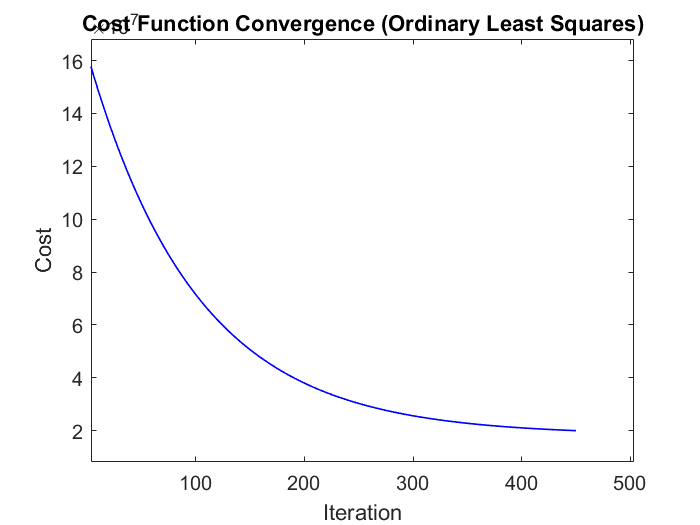

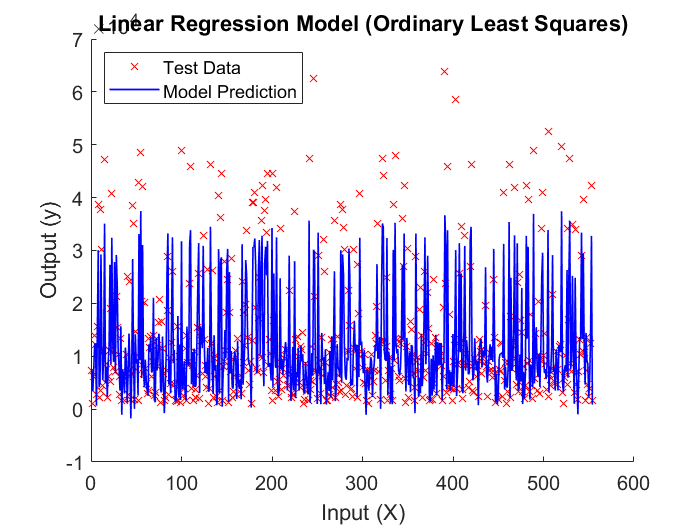

plotresult(X_test, Y_test, beta_hat_ols, epochs(1), cost_history_ols, "Ordinary Least Squares")

**Least Median Squares**

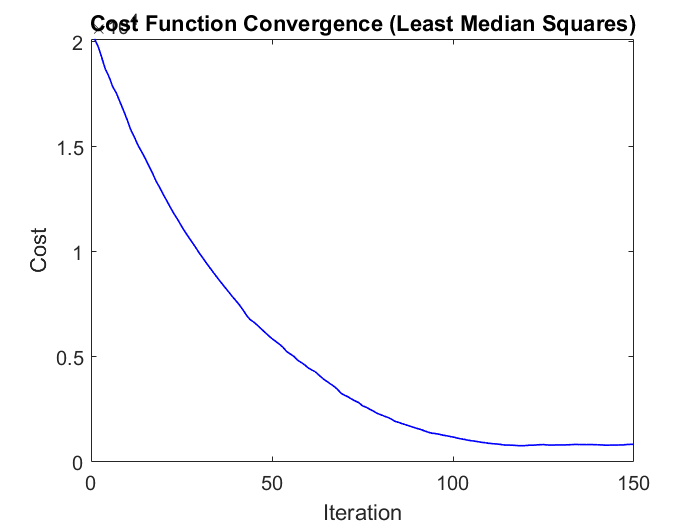

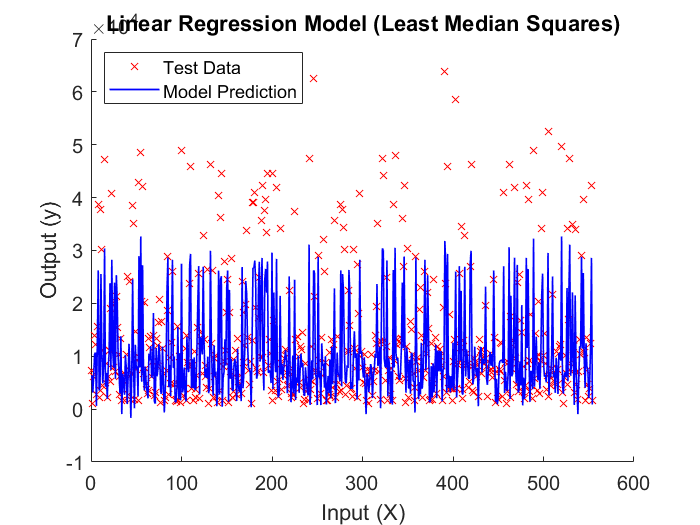

plotresult(X_test, Y_test, beta_hat_lms, epochs(2), cost_history_lms, "Least Median Squares")

**Least Trimmed Squares**

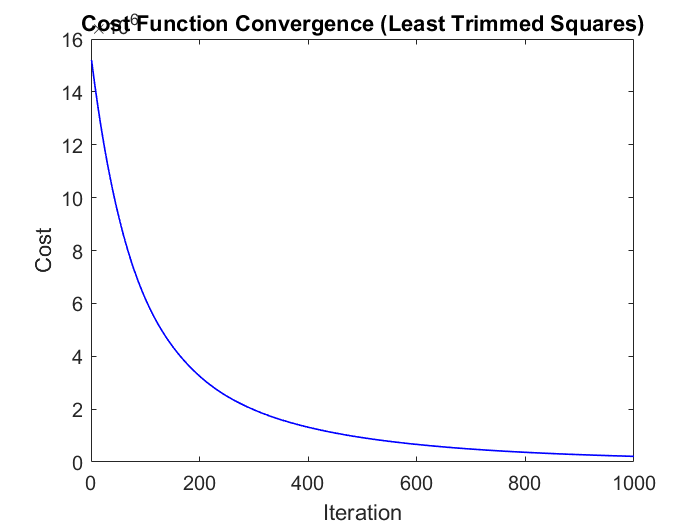

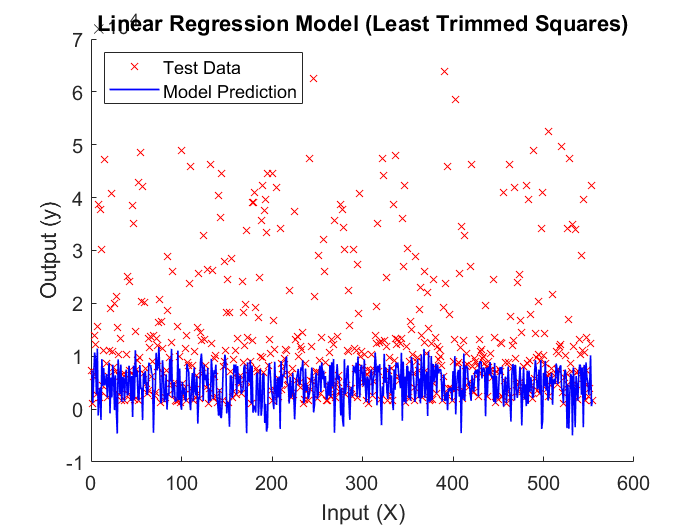

plotresult(X_test, Y_test, beta_hat_lts, epochs(3), cost_history_lts, "Least Trimmed Squares")

## Compare Models

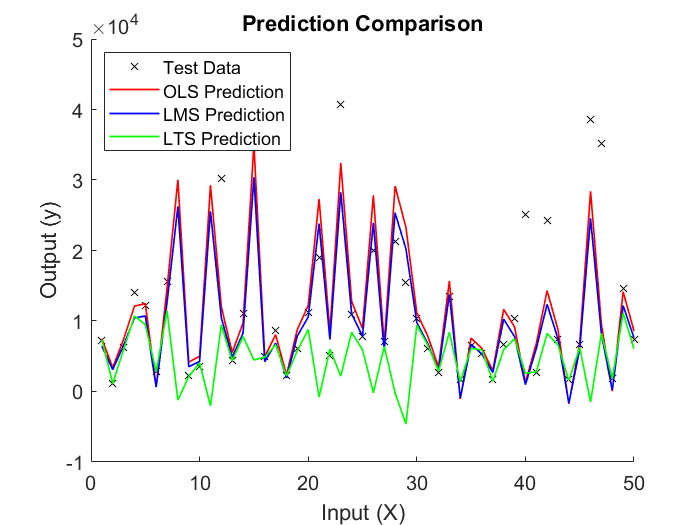

m = length(Y_test);
Xt = [ones(m, 1) X_test];
y_ols = Xt*beta_hat_ols;
y_lms = Xt*beta_hat_lms;
y_lts = Xt*beta_hat_lts;

%% Linear regression model plot

figure;
n = 50;
scatter(1:n, Y_test(1:n), 'kx', 'MarkerFaceColor', 'r'); % Exclude bias term from X
hold on;
plot(1:n, y_ols(1:n), 'r-', 'LineWidth', 1);
plot(1:n, y_lms(1:n), 'b-', 'LineWidth', 1);
plot(1:n, y_lts(1:n), 'g-', 'LineWidth', 1);
legend('Test Data', 'OLS Prediction', 'LMS Prediction', 'LTS Prediction', 'Location', 'NorthWest');
xlabel('Input (X)', 'FontSize', 14);
ylabel('Output (y)', 'FontSize', 14);
title('Prediction Comparison', 'FontSize', 14);
set(gca, 'FontSize', 12); % Set font size for axis labels and ticks
hold off;


mse_ols = mean((Y_test-y_ols).^2);
mse_lms = mean((Y_test-y_lms).^2);
mse_lts = mean((Y_test-y_lts).^2);

% Display metrics
TM = table(mse_ols, mse_lms, mse_lts, 'VariableNames', methods);
TMD = table({'MSE'}, TM, 'VariableNames', {'Parameters', 'Metrics'});
disp(TMD);

    Parameters                   Metrics               
                     OLS           LMS           LTS   
    __________    _____________________________________

      'MSE'       3.9839e+07    5.0851e+07    2.664e+08

